## Homework 7

#### Saray Valdez Hernandez

clear all
close all
clc

The equations of motion for projectile subject to air resistance are:

              $\begin{array}{l}
\frac{\textrm{du}}{\textrm{dt}}=-\gamma |\overrightarrow{V|} u\\
\frac{\textrm{dv}}{\textrm{dt}}=-\gamma |\overrightarrow{V|} v-g\\
\frac{\textrm{dx}}{\textrm{dt}}=u\\
\frac{\textrm{dy}}{\textrm{dt}}=v
\end{array}$   where    $\begin{array}{l}
u\;\mathrm{and}\;v\;\mathrm{are}\;\mathrm{velocity}\;\mathrm{components}\\
\overrightarrow{V} \;\mathrm{is}\;\mathrm{the}\;\mathrm{velocity}\;\mathrm{vector}\;\mathrm{whose}\;\mathrm{magnitude}\;\mathrm{is}\;\mathrm{the}\;\mathrm{speed}\;|\overrightarrow{V|} =\sqrt{u^2 +v^2 }\\
\gamma \;\mathrm{is}\;\mathrm{the}\;\mathrm{drag}\;\mathrm{coefficient}\;\left(\mathrm{aka}\;\mathrm{friction}\;\mathrm{coefficient}\right)\\
g\;\mathrm{is}\;\mathrm{gravity}\;\\
t\;\mathrm{is}\;\mathrm{time}
\end{array}$ 

Setting the initial conditions

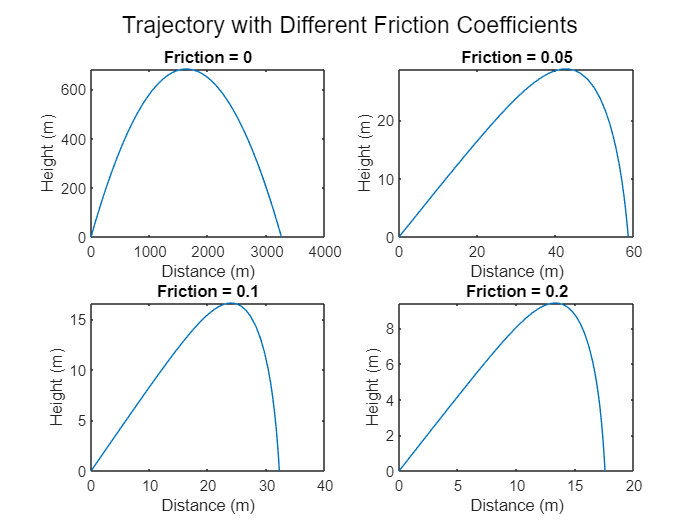

x(1)=0; x0=x(1); % setting initial x value
y(1)=0; y0=y(1); %setting initial y value

%parameters for initial u and v 
mag_velocity=180; % setting the initial speed to 180 m/s
theta=40; %setting launch angle to 40 degrees

u(1)=mag_velocity*cosd(theta); u0=u(1); %setting initial u value
v(1)=mag_velocity*sind(theta); v0=v(1); %setting initial v value

%create vector of initial conditions
X0=[ u0 v0 x0 y0];

%setting parameters for function
gravity=9.8; %m/s^2
friction=[0 0.05 0.1 0.2];
tspan=[0,25];

for j=1:length(friction);
    p=[friction(j) gravity];
    [t,x]=ode45(@air_res,tspan,X0,[],p);

    figure(1)
    subplot(2,2,j);
    plot(x(:,3),x(:,4));
    %sgtitle('Trajectory for Different Friction Coefficients')
    title(['Friction = ', num2str(friction(j))]);
    xlabel('Distance (m)'); ylabel('Height (m)');
    ylim([0 inf]);
end